# Soil test figures

This file is also for illustration of the soil simulations after 30 years for the different model versions.

## Soil model including only leaching flux

This model does not account for biological processes. It was used to determine the contribution of the leaching flux for the long-term soil predictions. From this analysis, we concluded that the biological processes are important for describing long-term atrazine and hydroxyatrazine degradation. 

% Calling Parameters %

p1(9)  = (3.2);     % Freundlich coeff of AT 
p1(10) = (0.85);    % Freundlich exponent of AT 
p1(11) = (17.4);      % Freundlich coeff of HY 
p1(12) = (0.85);    % Freundlich exponent of HY

% Calling fixed parameters %

delta13_I = (-29/1000);
AT_tot    =  0*(8*12/216);                  % Input of AT, including light and heavy isotopologues [microg C/L]
frac_coef = -0.0054;                        % Initial fraction Coefficient for the AT applied in the experiment "epsilon" initial
SN        = (delta13_I+1)*0.011180;         % Initial C13/C12. -29 is taken from Ehrl et. al 2019 paper (-29 per mil)

q(2) = AT_tot;                                  % Concentration of light AT in the inlet [microg C/L]
q(3) = AT_tot*SN;                               % Concentration of heavier AT in the inlet [microg C/L]
q(4) = 1;                                       % Factor for chemostat (1) and retentostat (0).
q(5) = 8*12/216;                                % mg C/mg AT
q(6) = 8*12/197;                                % mg C/mg HY
q(7) = 1e-15;                                   % Volume of a single bacterium [L]
q(8) = 1+frac_coef;                             % Isotopic fractionation factor "alpha" that comes from the enzymatic activity [-]
q(9) = 0.011180;                                % reference isotope ratio of VPDB (Vienna Pee Dee Belemnite) [-]
q(10)= 0.35;                                    % Average volumetric soil water content [cm^3 cm^-3]
q(11)= 1.2;                                     % Bulk density of soils [g cm^-3]
q(12)= (0.63+0.5)/2/300;                        % Leaching velocity per day [d^-1] 


## Calling the model

% ODE options %

abstol = 1e-9;
reltol = 1e-9;
o_opts = odeset('AbsTol',abstol,'RelTol',reltol,'Events',@stopevent,'NonNegative',1:3);

% Extra parameters %

C_AT     = q(5);            % µg C/µg AT
C_HY     = q(6);            % µg C/µg HY
isf      = q(8);            % Isotopic fractionation factor (?)
Ref      = q(9);            % reference isotope ratio of VPDB
C_tot    = 1e3*C_AT;        % µg C/Kg 
C_L0     = 0;
th_V     = q(10);           % Average volumetric soil water content (cm^3 cm^-3)
rho_B    = q(11);           % Bulk density of soils (g cm^-3)
K_F      = p1(9);
n_F      = p1(10);
K_F_H    = p1(11);
n_F_H    = p1(12);
p1(13)   = 30e-9*1e3*1e3;   % M

% Determination of sorbed pesticide % 

fun=@(C_L0) MCPA_init(C_L0,C_tot,K_F,n_F,th_V,rho_B);
%  switch off solver progress information on solver progress of fsolve
f_opts = optimoptions('fsolve','Display','none');
% calculate initial MCPA in solution phase
C_L0 = fsolve(fun,C_L0,f_opts); 
ATinitC  = C_L0;  % µg C/ L OUTSIDE

% Intitial Conditions %

        c(1)    = ATinitC;                      % Lighter AT outside the cell in the system in solution [µg C/L]
        c(2)    = ATinitC*SN;                   % Heavier AT outside the cell in the system in solution [µg C/L]
        c(3)    = 0;                            % Hydroxyatrazine outisde the cell [µg C/L]
        
% Time vector %

time = linspace(0,10950,10950);

## Running ODE

[ty,cu] = ode15s(@variant_0_leaching,time,c,o_opts,p1',q);

## Output post-processing

        AT_outlr     = (cu(:,1).*th_V/rho_B+K_F.*cu(:,1).^n_F)/C_AT;     % AT lighter
        AT_outhr     = (cu(:,2).*th_V/rho_B+K_F.*cu(:,2).^n_F)/C_AT;     % AT heavier 
        AT_outTr     = AT_outlr + AT_outhr; % Total AT
        
        AT_outlrS     = (cu(:,1))/C_AT;     % AT lighter
        AT_outhrS     = (cu(:,2))/C_AT;     % AT heavier 
        AT_outTrS     = AT_outlrS + AT_outhrS; % Total AT
        
        HY_outr      = (cu(:,3).*th_V/rho_B+K_F_H.*cu(:,3).^n_F_H)/C_HY; % HY
        
        Timeor       = (ty);               % Time    

## Plotting

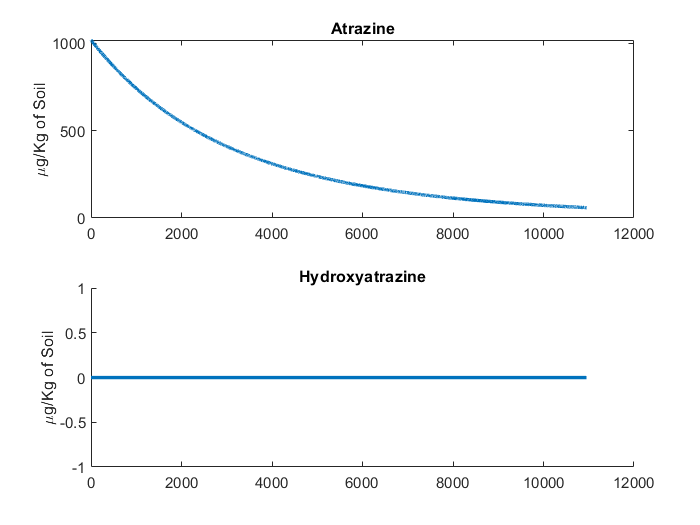

figure ('Name','AT-Chemostat')
subplot (2,1,1);
plot(Timeor,AT_outTr,'LineWidth',2)
hold on
ylabel('\mug/Kg of Soil')
title('Atrazine')
hold off

subplot (2,1,2);
hold on
plot(Timeor,HY_outr,'LineWidth',2)
ylabel('\mug/Kg of Soil')
title('Hydroxyatrazine')
hold off

## Soil model based on variant 1 

This model is based on model variant 1 (Monod Model) with and without leaching. We provide the example using calibrated kinetic parametes against the retentostat data, which outperformed the chemostat calibration. 

% Calling Parameters %
load('C:\Doctorado\Programa\Nuevo_PECCAD\NEW ATRAZINE\GENE BASED MODELS\AT_engi_soil\example_parameter_fits\variant_1_retentostat.mat')
p1     = p;
p1(9)  = (3.2);         % Freundlich coeff of AT 
p1(10) = (0.85);        % Freundlich exponent of AT 
p1(11) = (17.4);        % Freundlich coeff of HY 
p1(12) = (0.85);        % Freundlich exponent of HY

% Calling fixed parameters %
delta13_I = (-29/1000);
AT_tot    =  0*(8*12/216);                  % Input of AT, including light and heavy isotopologues [microg C/L]
frac_coef = -0.0054;                        % Initial fraction Coefficient for the AT applied in the experiment "epsilon" initial
SN        = (delta13_I+1)*0.011180;         % Initial C13/C12. -29 is taken from Ehrl et. al 2019 paper (-29 per mil)

q(2) = AT_tot;                                  % Concentration of light AT in the inlet [microg C/L]
q(3) = AT_tot*SN;                               % Concentration of heavier AT in the inlet [microg C/L]
q(4) = 1;                                       % Factor for chemostat (1) and retentostat (0).
q(5) = 8*12/216;                                % mg C/mg AT
q(6) = 8*12/197;                                % mg C/mg HY
q(7) = 1e-15;                                   % Volume of a single bacterium [L]
q(8) = 1+frac_coef;                             % Isotopic fractionation factor "alpha" that comes from the enzymatic activity [-]
q(9) = 0.011180;                                % reference isotope ratio of VPDB (Vienna Pee Dee Belemnite) [-]
q(10)= 0.35;                                    % Average volumetric soil water content [cm^3 cm^-3]
q(11)= 1.2;                                     % Bulk density of soils [g cm^-3]
q(12)= (0.63+0.5)/2/300;                        % Leaching velocity per day [d^-1] 


## Calling the models

% ODE options %
abstol = 1e-9;
reltol = 1e-9;
o_opts = odeset('AbsTol',abstol,'RelTol',reltol,'Events',@stopevent,'NonNegative',1:7);

% Extra parameters %
T_bioC   = 1.5e10;          % Initial Biomass [cells/Kg]
fcell    = 10^p1(7);
C_AT     = q(5);            % µg C/µg AT
C_HY     = q(6);            % µg C/µg HY
isf      = q(8);            % Isotopic fractionation factor (?)
Ref      = q(9);            % reference isotope ratio of VPDB
C_tot    = 1e3*C_AT;        % Total initial MCPA conc. mmol g-1 soil
C_L0     = 0;
th_V     = q(10);           % Average volumetric soil water content (cm^3 cm^-3)
rho_B    = q(11);           % Bulk density of soils (g cm^-3)
K_F      = p1(9);
n_F      = p1(10);
K_F_H    = p1(11);
n_F_H    = p1(12);
p1(13)   = 30e-9*1e3*1e3;   % M

% Determination of sorbed pesticide % 

fun=@(C_L0) MCPA_init(C_L0,C_tot,K_F,n_F,th_V,rho_B);
%  switch off solver progress information on solver progress of fsolve
f_opts = optimoptions('fsolve','Display','none');
% calculate initial MCPA in solution phase
C_L0 = fsolve(fun,C_L0,f_opts); % MCPA in solution
ATinitC  = C_L0;  % µg C/ L OUTSIDE

% Initial Conditions %

        c(1)    = p1(13);                   % Active bacteria A biomass [µg C/L]
        c(2)    = 0;                        % Lighter AT inside the cell in the system in solution [µg C/L]
        c(3)    = 0;                        % Heavier AT inside the cell in the system in solution [µg C/L]
        c(4)    = ATinitC;                  % Lighter AT outside the cell in the system in solution [µg C/L]
        c(5)    = ATinitC*SN;               % Heavier AT outside the cell in the system in solution [µg C/L]
        c(6)    = 0;                        % Hydroxyatrazine INSIDE the cell [µg C/L]
        c(7)    = 0;                        % Hydroxyatrazine outisde the cell [µg C/L]
        
% Time vector %

time = linspace(0,10950,10950); 


## Running ODE for model variant 1

[ty,cu] = ode15s(@variant_1,time,c,o_opts,p1',q);

% Post-processing %
        Lcellr       = (cu(:,1))/fcell;    % Biomass 
        AT_outlr     = (cu(:,4).*th_V/rho_B+K_F.*cu(:,4).^n_F)/C_AT;     % AT lighter
        AT_outhr     = (cu(:,5).*th_V/rho_B+K_F.*cu(:,5).^n_F)/C_AT;     % AT heavier 
        AT_outTr     = AT_outlr + AT_outhr; % Total AT
        
        AT_outlrS     = (cu(:,4))/C_AT;     % AT lighter
        AT_outhrS     = (cu(:,5))/C_AT;     % AT heavier 
        AT_outTrS     = AT_outlrS + AT_outhrS; % Total AT
        
        HY_outr      = (cu(:,7).*th_V/rho_B+K_F_H.*cu(:,7).^n_F_H)/C_HY; % HY
        
        Timeor       = (ty);               % Time
        

## Plotting

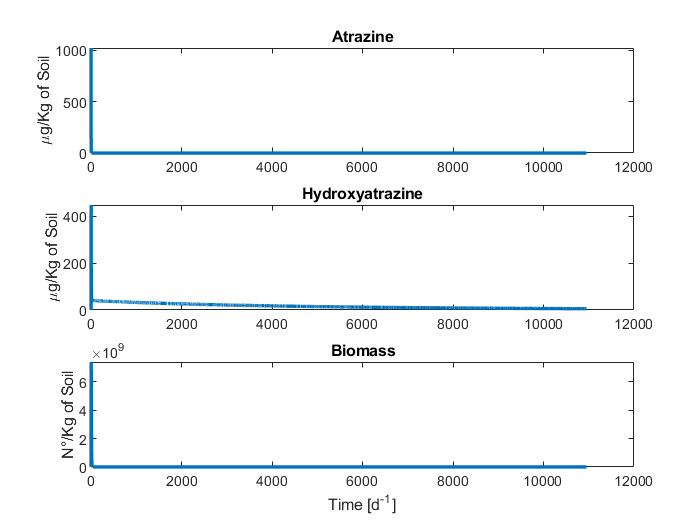

figure ('Name','Variant 1')

subplot (3,1,1);
plot(Timeor,AT_outTr,'LineWidth',2)
ylabel('\mug/Kg of Soil')
title('Atrazine')

subplot (3,1,2);
plot(Timeor,HY_outr,'LineWidth',2)
ylabel('\mug/Kg of Soil')
title('Hydroxyatrazine')

subplot (3,1,3);
plot(Timeor,Lcellr,'LineWidth',2)
xlabel('Time [d^{-1}]')
ylabel('N°/Kg of Soil')
title('Biomass')

## Running ODE for model variant 1 + leaching

[ty1,cu1] = ode15s(@variant_1_leaching,time,c,o_opts,p1',q);

% Post-processing %
        Lcellr1       = (cu1(:,1))/fcell;    % Biomass 
        AT_outlr1     = (cu1(:,4).*th_V/rho_B+K_F.*cu1(:,4).^n_F)/C_AT;     % AT lighter
        AT_outhr1     = (cu1(:,5).*th_V/rho_B+K_F.*cu1(:,5).^n_F)/C_AT;     % AT heavier 
        AT_outTr1     = AT_outlr + AT_outhr; % Total AT
        
        AT_outlrS1     = (cu1(:,4))/C_AT;     % AT lighter
        AT_outhrS1     = (cu1(:,5))/C_AT;     % AT heavier 
        AT_outTrS1     = AT_outlrS + AT_outhrS; % Total AT
        
        HY_outr1      = (cu1(:,7).*th_V/rho_B+K_F_H.*cu1(:,7).^n_F_H)/C_HY; % HY
        
        Timeor1       = (ty1);               % Time

## Plotting

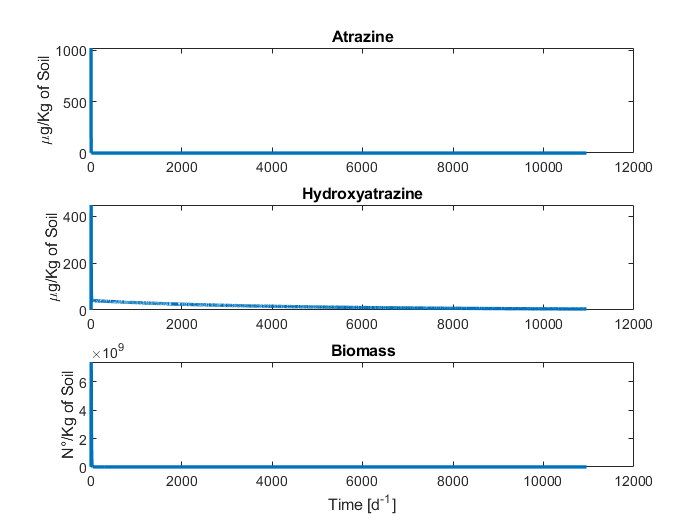

figure ('Name','variant 1 + Leaching')

subplot (3,1,1);
plot(Timeor1,AT_outTr1,'LineWidth',2)
ylabel('\mug/Kg of Soil')
title('Atrazine')

subplot (3,1,2);
plot(Timeor1,HY_outr1,'LineWidth',2)
ylabel('\mug/Kg of Soil')
title('Hydroxyatrazine')

subplot (3,1,3);
plot(Timeor1,Lcellr1,'LineWidth',2)
xlabel('Time [d^{-1}]')
ylabel('N°/Kg of Soil')
title('Biomass')

## Soil model based on variant 2 

This model is based on model variant 2 (Thermodynamic Model) with and without leaching. We provide the example using calibrated kinetic parametes against the retentostat data, which outperformed the chemostat calibration. 

% Calling Parameters %
load('C:\Doctorado\Programa\Nuevo_PECCAD\NEW ATRAZINE\GENE BASED MODELS\AT_engi_soil\example_parameter_fits\variant_2_retentostat.mat')
p1     = p;
p1(9)  = (3.2);         % Freundlich coeff of AT 
p1(10) = (0.85);        % Freundlich exponent of AT 
p1(11) = (17.4);        % Freundlich coeff of HY 
p1(12) = (0.85);        % Freundlich exponent of HY

% Calling fixed parameters %
delta13_I = (-29/1000);
AT_tot    =  0*(8*12/216);                  % Input of AT, including light and heavy isotopologues [microg C/L]
frac_coef = -0.0054;                        % Initial fraction Coefficient for the AT applied in the experiment "epsilon" initial
SN        = (delta13_I+1)*0.011180;         % Initial C13/C12. -29 is taken from Ehrl et. al 2019 paper (-29 per mil)

q(2) = AT_tot;                                  % Concentration of light AT in the inlet [microg C/L]
q(3) = AT_tot*SN;                               % Concentration of heavier AT in the inlet [microg C/L]
q(4) = 1;                                       % Factor for chemostat (1) and retentostat (0).
q(5) = 8*12/216;                                % mg C/mg AT
q(6) = 8*12/197;                                % mg C/mg HY
q(7) = 1e-15;                                   % Volume of a single bacterium [L]
q(8) = 1+frac_coef;                             % Isotopic fractionation factor "alpha" that comes from the enzymatic activity [-]
q(9) = 0.011180;                                % reference isotope ratio of VPDB (Vienna Pee Dee Belemnite) [-]
q(10)= 0.35;                                    % Average volumetric soil water content [cm^3 cm^-3]
q(11)= 1.2;                                     % Bulk density of soils [g cm^-3]
q(12)= (0.63+0.5)/2/300;                        % Leaching velocity per day [d^-1] 


## Calling the models

% ODE options %
abstol = 1e-9;
reltol = 1e-9;
o_opts = odeset('AbsTol',abstol,'RelTol',reltol,'Events',@stopevent,'NonNegative',1:7);

% Extra parameters %
T_bioC   = 1.5e10;          % Initial Biomass [cells/Kg]
fcell    = 10^p1(7);
C_AT     = q(5);            % µg C/µg AT
C_HY     = q(6);            % µg C/µg HY
isf      = q(8);            % Isotopic fractionation factor (?)
Ref      = q(9);            % reference isotope ratio of VPDB
C_tot    = 1e3*C_AT;        % Total initial MCPA conc. mmol g-1 soil
C_L0     = 0;
th_V     = q(10);           % Average volumetric soil water content (cm^3 cm^-3)
rho_B    = q(11);           % Bulk density of soils (g cm^-3)
K_F      = p1(9);
n_F      = p1(10);
K_F_H    = p1(11);
n_F_H    = p1(12);
p1(13)   = 30e-9*1e3*1e3;   % M

% Determination of sorbed pesticide % 

fun=@(C_L0) MCPA_init(C_L0,C_tot,K_F,n_F,th_V,rho_B);
%  switch off solver progress information on solver progress of fsolve
f_opts = optimoptions('fsolve','Display','none');
% calculate initial MCPA in solution phase
C_L0 = fsolve(fun,C_L0,f_opts); % MCPA in solution
ATinitC  = C_L0;  % µg C/ L OUTSIDE

% Initial Conditions %

        c(1)    = p1(13);                   % Active bacteria A biomass [µg C/L]
        c(2)    = 0;                        % Lighter AT inside the cell in the system in solution [µg C/L]
        c(3)    = 0;                        % Heavier AT inside the cell in the system in solution [µg C/L]
        c(4)    = ATinitC;                  % Lighter AT outside the cell in the system in solution [µg C/L]
        c(5)    = ATinitC*SN;               % Heavier AT outside the cell in the system in solution [µg C/L]
        c(6)    = 0;                        % Hydroxyatrazine INSIDE the cell [µg C/L]
        c(7)    = 0;                        % Hydroxyatrazine outisde the cell [µg C/L]
        
% Time vector %

time = linspace(0,10950,10950); 


## Running ODE for model variant 1

[ty,cu] = ode15s(@variant_2,time,c,o_opts,p1',q);

% Post-processing %
        Lcellr       = (cu(:,1))/fcell;    % Biomass 
        AT_outlr     = (cu(:,4).*th_V/rho_B+K_F.*cu(:,4).^n_F)/C_AT;     % AT lighter
        AT_outhr     = (cu(:,5).*th_V/rho_B+K_F.*cu(:,5).^n_F)/C_AT;     % AT heavier 
        AT_outTr     = AT_outlr + AT_outhr; % Total AT
        
        AT_outlrS     = (cu(:,4))/C_AT;     % AT lighter
        AT_outhrS     = (cu(:,5))/C_AT;     % AT heavier 
        AT_outTrS     = AT_outlrS + AT_outhrS; % Total AT
        
        HY_outr      = (cu(:,7).*th_V/rho_B+K_F_H.*cu(:,7).^n_F_H)/C_HY; % HY
        
        Timeor       = (ty);               % Time
        

## Plotting

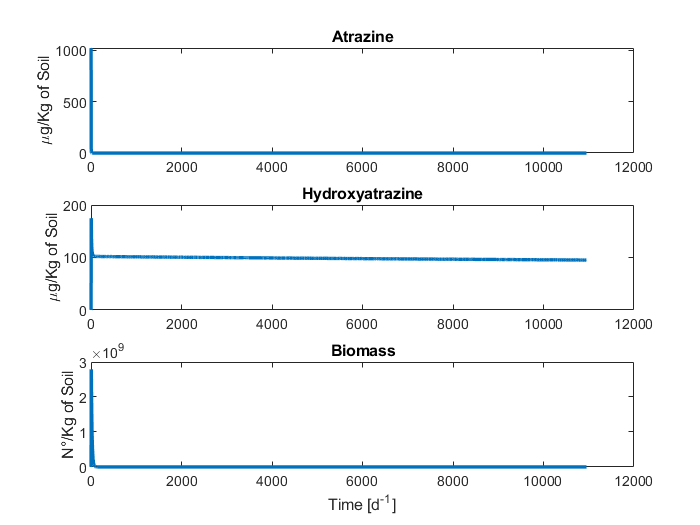

figure ('Name','Variant 1')

subplot (3,1,1);
plot(Timeor,AT_outTr,'LineWidth',2)
ylabel('\mug/Kg of Soil')
title('Atrazine')

subplot (3,1,2);
plot(Timeor,HY_outr,'LineWidth',2)
ylabel('\mug/Kg of Soil')
title('Hydroxyatrazine')

subplot (3,1,3);
plot(Timeor,Lcellr,'LineWidth',2)
xlabel('Time [d^{-1}]')
ylabel('N°/Kg of Soil')
title('Biomass')

## Running ODE for model variant 1 + leaching

[ty1,cu1] = ode15s(@variant_2_leaching,time,c,o_opts,p1',q);

% Post-processing %
        Lcellr1       = (cu1(:,1))/fcell;    % Biomass 
        AT_outlr1     = (cu1(:,4).*th_V/rho_B+K_F.*cu1(:,4).^n_F)/C_AT;     % AT lighter
        AT_outhr1     = (cu1(:,5).*th_V/rho_B+K_F.*cu1(:,5).^n_F)/C_AT;     % AT heavier 
        AT_outTr1     = AT_outlr + AT_outhr; % Total AT
        
        AT_outlrS1     = (cu1(:,4))/C_AT;     % AT lighter
        AT_outhrS1     = (cu1(:,5))/C_AT;     % AT heavier 
        AT_outTrS1     = AT_outlrS + AT_outhrS; % Total AT
        
        HY_outr1      = (cu1(:,7).*th_V/rho_B+K_F_H.*cu1(:,7).^n_F_H)/C_HY; % HY
        
        Timeor1       = (ty1);               % Time

## Plotting

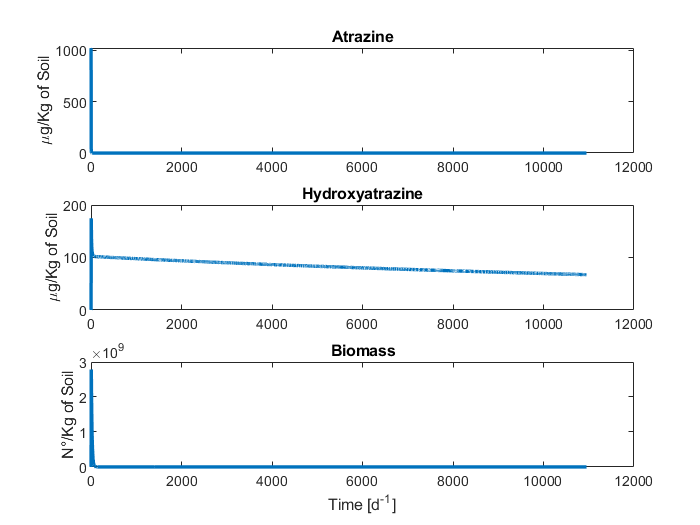

figure ('Name','variant 1 + Leaching')

subplot (3,1,1);
plot(Timeor1,AT_outTr1,'LineWidth',2)
ylabel('\mug/Kg of Soil')
title('Atrazine')

subplot (3,1,2);
plot(Timeor1,HY_outr1,'LineWidth',2)
ylabel('\mug/Kg of Soil')
title('Hydroxyatrazine')

subplot (3,1,3);
plot(Timeor1,Lcellr1,'LineWidth',2)
xlabel('Time [d^{-1}]')
ylabel('N°/Kg of Soil')
title('Biomass')